# **Projeto 2 - Mecânica dos Sólidos**

format short e

## **Aula 24:** Exercício 1

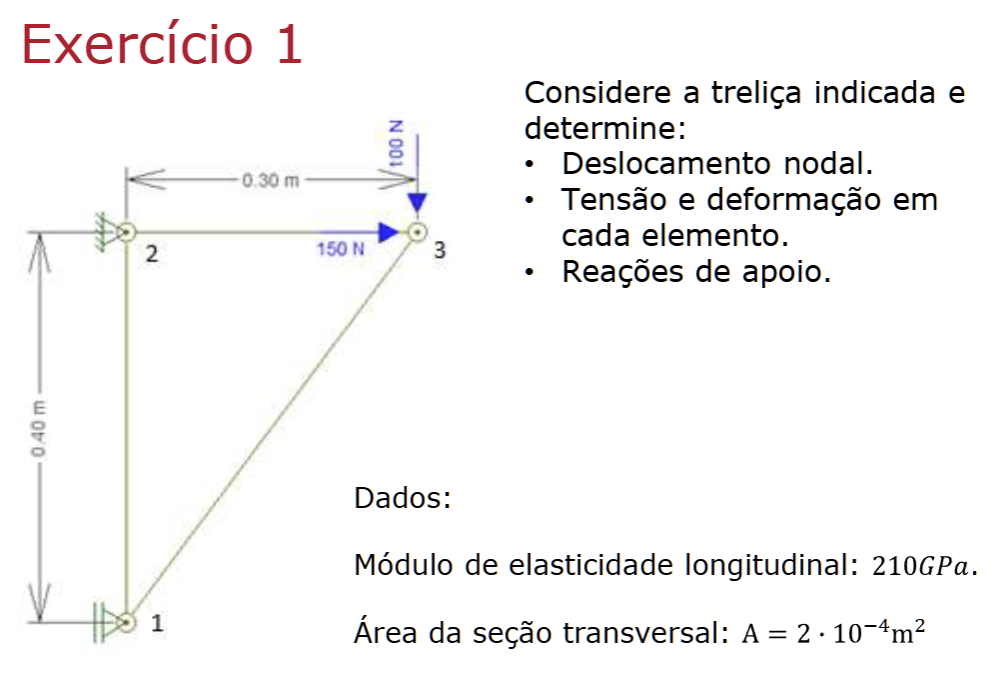

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL.

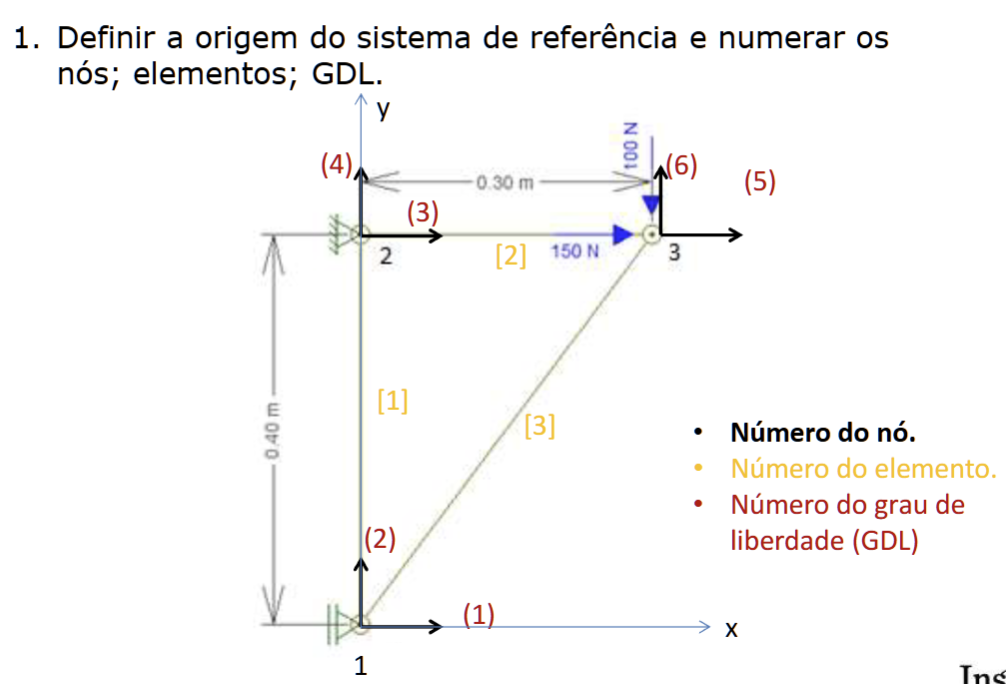

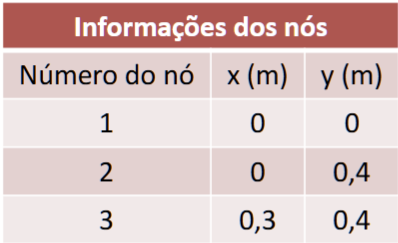

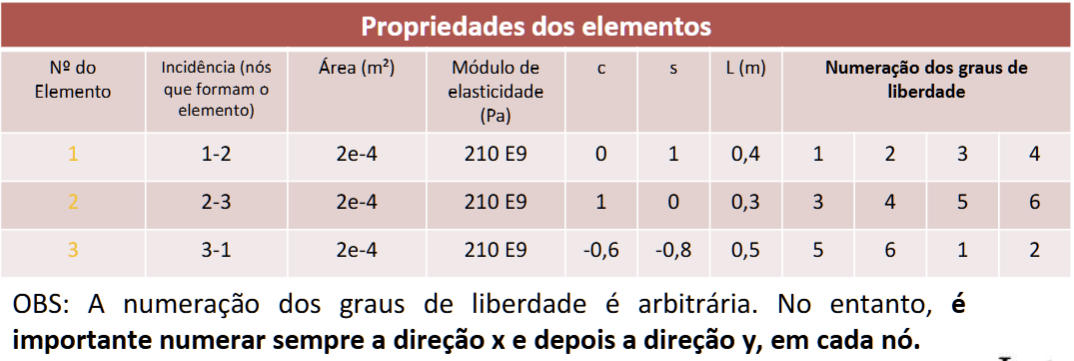

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9; % Módulo de elasticidade longitudinal [Pa]
A = 2 * 10^(-4); % Área da seção transversal [m^2]

num_elementos = 3;

% X e Y de cada nó

%       x    y
x_y = [ 0,   0;
        0,  0.4;
        0.3,0.4];

% Comprimento dos elementos (e)
l1 = 0.4;                   % [m]
l2 = 0.3;                   % [m]
l3 = sqrt((l1^2) + (l2^2)); % [m]

len_elementos = zeros(length(x_y), 1);
for i = 1:num_elementos
    if i == num_elementos
        delta_x = round(abs(x_y(num_elementos,0) - x_y(1,0)));
        delta_y = round(abs(x_y(num_elementos,1) - x_y(1,1)));
    else
        delta_x = round(abs(x_y(i,0) - x_y(i+1,0)));
        delta_y = round(abs(x_y(i,1) - x_y(i+1,1)));
    end
    len_elementos(i) = sqrt(delta_x^2 + delta_y^2);
end

Index in position 2 is invalid. Array indices must be positive integers or logical values.

len_elementos

% Cossenos (c) e senos (s)
c1 = 0; s1 = 1;
c2 = 1; s2 = 0;
c3 = (x1 - x3)/l3; s3 = (y1 - y3)/l3;

sen_cos_el = [ s1, c1;
               s2, c2;
               s3, c3 ];

% Matriz de Senos e Cossenos de cada elemento
cos_sens_e1 = [c1^2,    c1*s1, -c1^2,  -c1*s1;
               c1*s1,   s1^2,  -c1*s1, -s1^2;
              -c1^2,   -c1*s1,  c1^2,   c1*s1;
              -c1*s1,  -s1^2,   c1*s1,  s1^2];

cos_sens_e2 = [c2^2,    c2*s2, -c2^2,  -c2*s2;
               c2*s2,   s2^2,  -c2*s2, -s2^2;
              -c2^2,   -c2*s2,  c2^2,   c2*s2;
              -c2*s2,  -s2^2,   c2*s2,  s2^2];

cos_sens_e3 = [c3^2,    c3*s3, -c3^2,  -c3*s3;
               c3*s3,   s3^2,  -c3*s3, -s3^2;
              -c3^2,   -c3*s3,  c3^2,   c3*s3;
              -c3*s3,  -s3^2,   c3*s3,  s3^2];

% Matrizes de Rigidez de cada elemento

K1 = ( E*A ) / l1 * cos_sens_e1;
K2 = ( E*A ) / l2 * cos_sens_e2;
K3 = ( E*A ) / l3 * cos_sens_e3

% PASSO 3: Montar a matriz de rigidez global [Kg] da treliça fazendo asuperposição das matrizes dos elementos.
% Funcionou de primeira 😎
Kg = [K1(1,1) + K3(3,3),  K1(1,2) + K3(3,4),  K1(1,3),            K1(1,4),            K3(3,1),           K3(3,2);
      K1(2,1) + K3(4,3),  K1(2,2) + K3(4,4),  K1(2,3),            K1(2,4),            K3(4,1),           K3(4,2);

      K1(3,1),            K1(3,2),            K1(3,3) + K2(1,1),  K1(3,4) + K2(1,2),  K2(1,3),           K2(1,4);
      K1(4,1),            K1(4,2),            K1(4,3) + K2(2,1),  K1(4,4) + K2(2,2),  K2(2,3),           K2(2,4);

      K3(1,3),            K3(1,4),            K2(3,1),            K2(3,2),            K2(3,3) + K3(1,1), K2(3,4) + K3(1,2);
      K3(2,3),            K3(2,4),            K2(4,1),            K2(4,2),            K2(4,3) + K3(2,1), K2(4,4) + K3(2,2)];

% PASSO 4: Montar o vetor global de forças. No grau de liberdade com restrição deve aparecer um esforço de reação.
Pg = [0; 0; 0; 0; 150; -100]

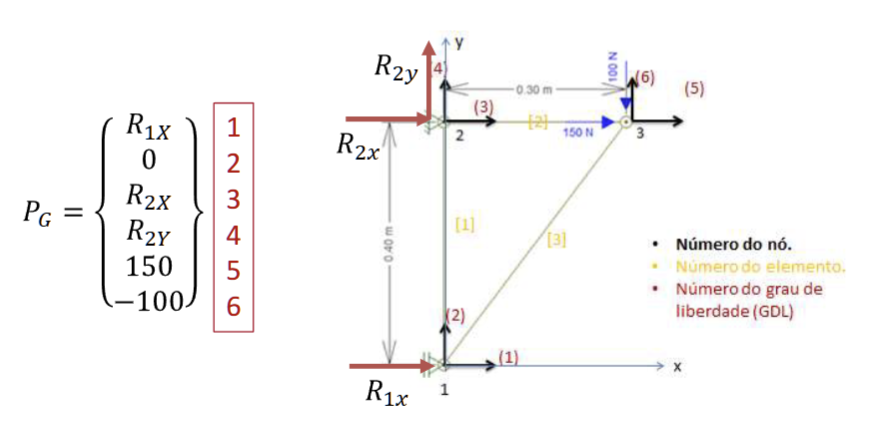

% PASSO 5: Aplicar as condições de contorno (eliminar linha e coluna do grau de liberdade com restrição)

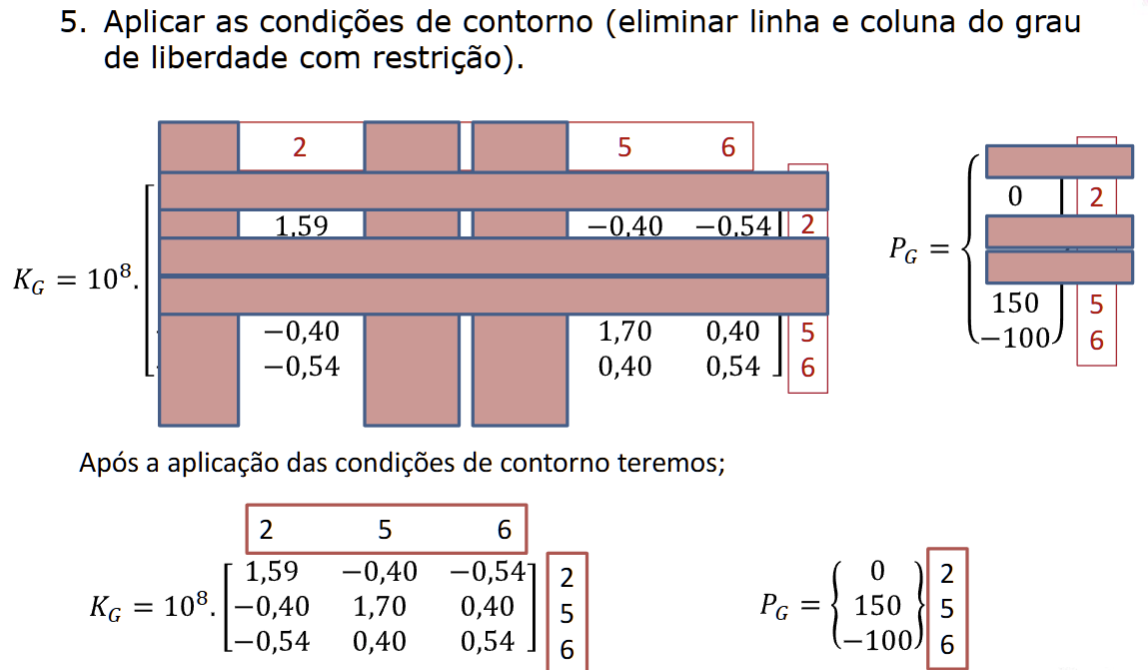

% Aplicando as condições de contorno temos:
Kg_reduzida = 10e8 * [Kg(2,2), Kg(2,5), Kg(2,6);
                      Kg(5,2), Kg(5,5), Kg(5,6);
                      Kg(6,2), Kg(6,5), Kg(6,6)]

Pg_reduzida = [Pg(2); Pg(5); Pg(6)]

% PASSO 6: Resolver o sistema de equações para a obtenção dos deslocamentos
%                      [Kg_reduzida] {U} = {Pg_reduzida}

U = linsolve(Kg_reduzida, Pg_reduzida);

U_expandida = [  0;
                U(1);
                 0;
                 0;
                U(2);
                U(3)]

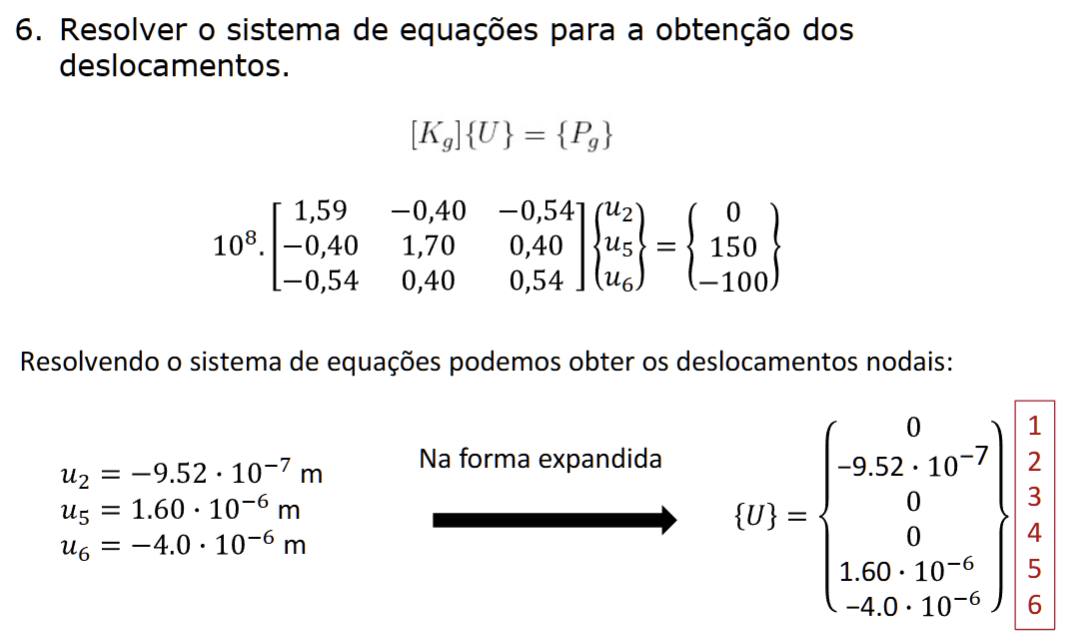

% PASSO 7: Determinar a deformação e a tensão em cada elemento.
len_U = length(U_expandida);
%deformacao = zeros(len_U/2, 1);  % como cada nó tem 2 u's
%tensao = zeros(len_U/2, 1);  % como cada nó tem 2 u's

%index_u = 1;
%for i = 1:len_U/2
%   if i == 1
%        %  def = (1 / len_el) * [ c, s, -c, -s ] * { u1; u2; u3; u4 }
%        aux = {U_expandida(i); U_expandida(i+1); U_expandida(i+2); U_expandida(i+3)}
%        deformacao(i) = (1/len_elementos(i)) * [ sen_cos_el(i,2), sen_cos_el(i,1), -sen_cos_el(i,1), -sen_cos_el(i,2)]
%   else 
%        deformacao(i) = 
%   end
%   tensao(i) = E*deformacao(i);
%   index_u = index_u + 2;
%end

deformacao = [ (1/len_elementos(1)) * [ -sen_cos_el(1,2), -sen_cos_el(1,1), sen_cos_el(1,2), sen_cos_el(1,1)] * [U_expandida(1); U_expandida(2); U_expandida(3); U_expandida(4)];
               (1/len_elementos(2)) * [ -sen_cos_el(2,2), -sen_cos_el(2,1), sen_cos_el(2,2), sen_cos_el(2,1)] * [U_expandida(3); U_expandida(4); U_expandida(5); U_expandida(6)];
               (1/len_elementos(3)) * [ -sen_cos_el(3,2), -sen_cos_el(3,1), sen_cos_el(3,2), sen_cos_el(3,1)] * [U_expandida(5); U_expandida(6); U_expandida(1); U_expandida(2)];
               ]
tensoes = E * deformacao

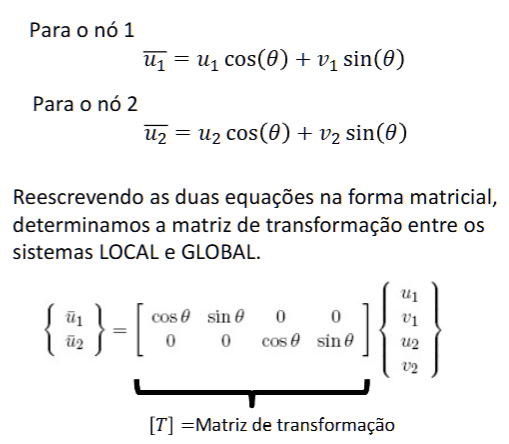

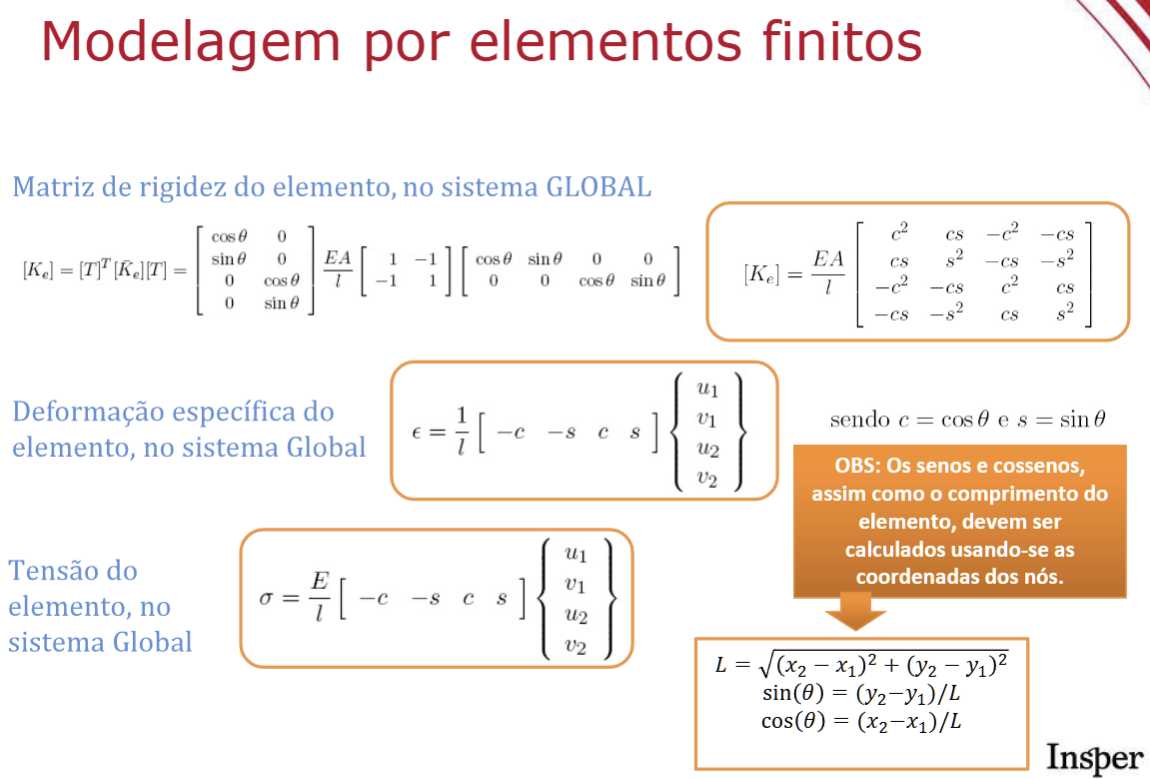

% PASSO 8: Determinar as reações de apoio nos nós com restrição.

Pg_final = eval(Kg * U_expandida)